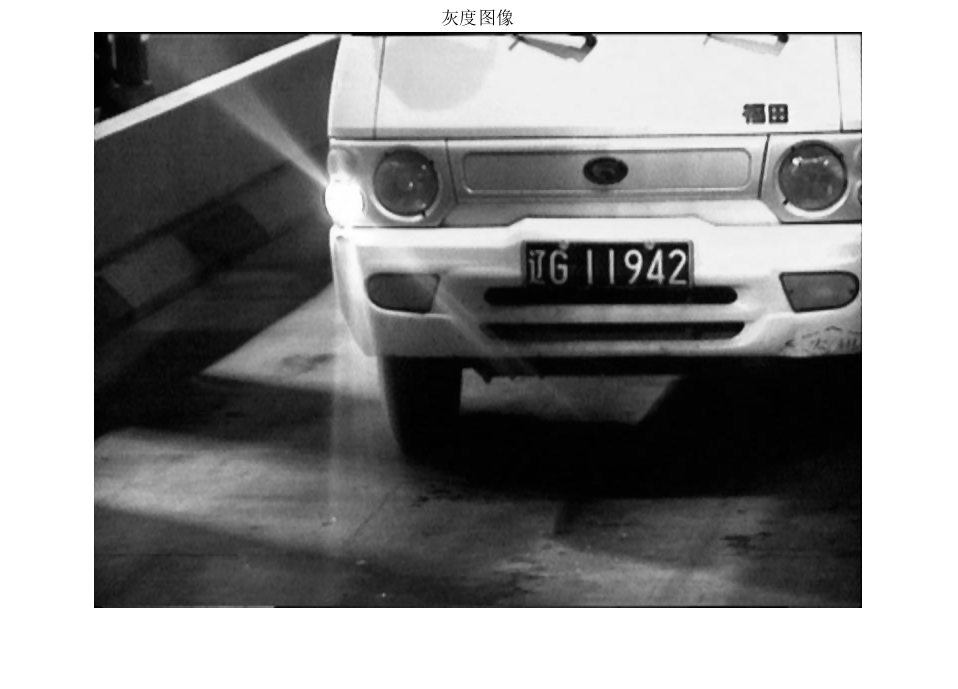

clc;clear;close all;
img = imread('images\04.jpg');
% 蓝色背景1，黄色背景2，其他3
color = 1;
% imshow(img);title('原始图像');

img_gray = preprocess(img);
imshow(img_gray);title("灰度图像");

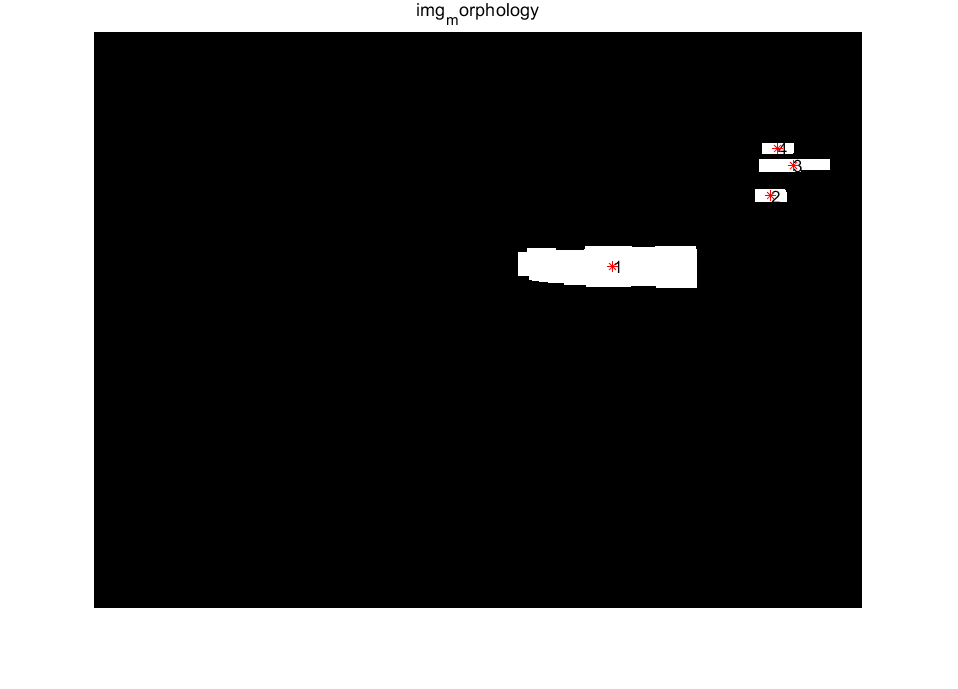

车牌候选区域的数量:4 


index_area =      1     0     0     0


index_color =    NaN   NaN   NaN   NaN


index_ratio =      1     1     0     1


index_sum =    NaN   NaN   NaN   NaN



[sobel_vertical,Prewitt_vertical,Roberts_vertical,log_vertical,Canny_vertical] = edge_detect(img_gray);
img_edge = Prewitt_vertical;
% imshow(img_edge);title("img_edge");


[img_morphology,bw_close,bw_remvoe,bw_open] = morphology(img_edge,1000);
img_morphology = judge(img_morphology,img);
imshow(img_morphology);title("img_morphology");

img_area = area_select(img_morphology,img,color);

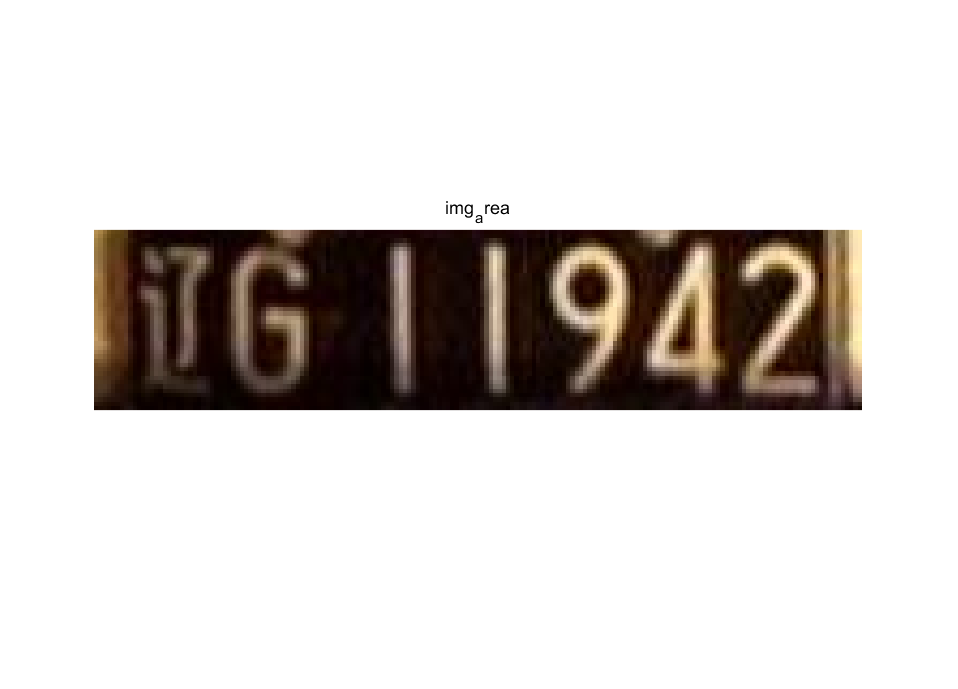

imshow(img_area);title("img_area");


% function img_gray = segmentation(img_area,color)
img_licence_gray = preprocess(img_area);
img_licence_binary = imbinarize(img_licence_gray,'adaptive');
[h,w] = size(img_licence_binary);
projection = sum(img_licence_binary, 1)/h;
sum_all = sum(projection);
if(sum_all/w>0.5)
    img_licence_binary = ones(h,w)-img_licence_binary;
    projection = ones(1,w)-projection;
end
imshow(img_licence_binary);title("img_licence_binary");
target_area = find(projection>0.11);
index = target_area(1);
index_list = [];
index_list(end+1) = index;
while(index<=w)
    next = index +1;
    if (ismember(next,target_area)==1)
        index = index + 1;
    else
        index_list(end+1)= index;
        index = target_area(find(target_area>index,1));
        index_size = size(index);
        if(index_size(2)~=0)
            index_list(end+1)= index;
        end
    end
end
num = length(index_list)/2;
for i = 1:num
    index_diff = index_list(2*i)-index_list(2*i-1);
end
index_diff(find(index_diff<5))=[]


index_diff =

  空的 1×0 double 行向量



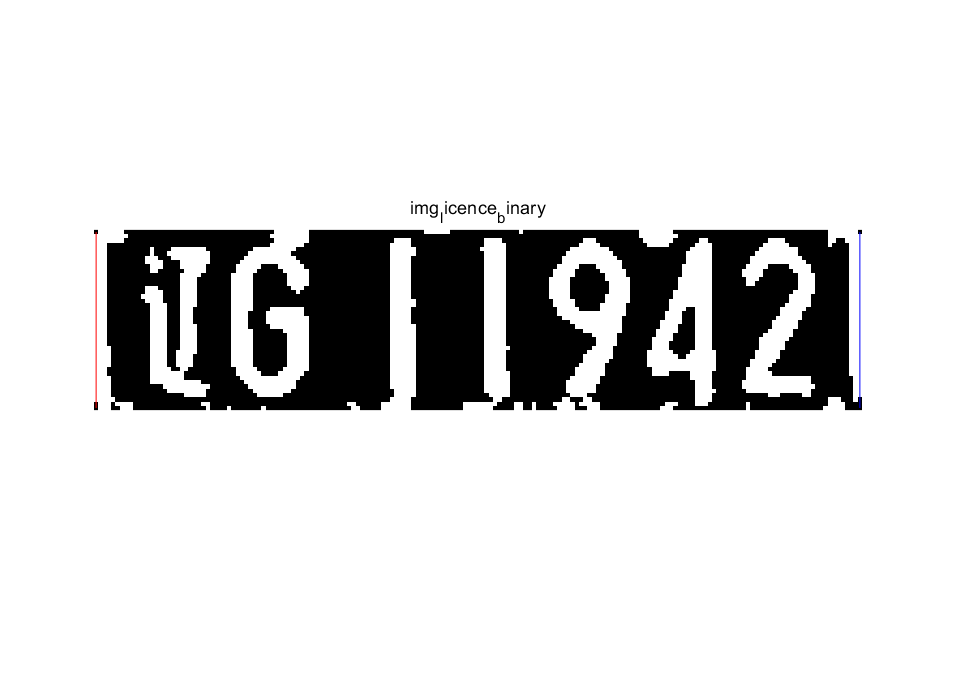

med_len = median(index_diff);
for i = 1:num
    mid = (index_list(2*i-1)+index_list(2*i))/2;
    index_new(2*i-1) =  floor(max(1,mid - med_len/2));
    index_new(2*i) = ceil(min(mid + med_len/2,w));
    
end
index_list = index_new;

hold on;
for index = index_list
    if(mod(find(index==index_list),2)==1)
        plot(index*ones(1,h),1:h,'r')
    else
        plot(index*ones(1,h),1:h,'b')
    end
end
hold off

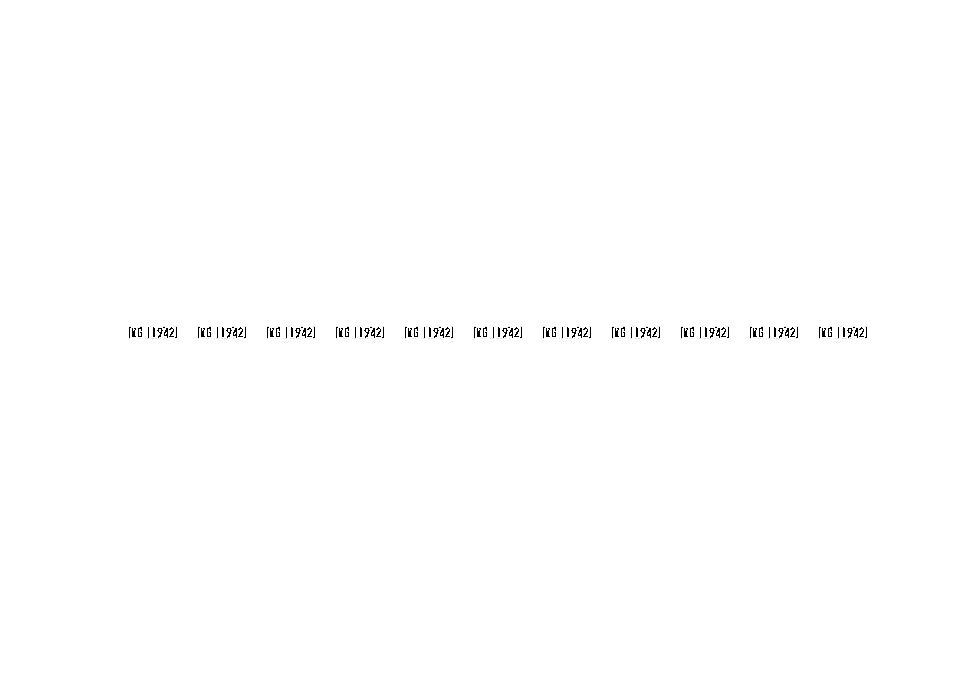


num = length(index_list)/2;
% for i = 1:num
%     subplot(1,num,i);
%     left = index_list(2*i-1);
%     right = index_list(2*i);
%     img_sub = img_area(:,left:right,:);
%     imshow(img_sub);
% end
img_licence_binary = ones(h,w)-img_licence_binary;
for i = 1:num
    subplot(1,num,i);
    left = index_list(2*i-1);
    right = index_list(2*i);
    img_sub = img_licence_binary(:,left:right,:);
    imshow(img_sub);
end




% end